# **Serial - Read Header Loopback**

This example shows you how to send and receive a ASCII data stream that contains multiple sub messages defined by a header string. The Simulink model can be configured for the serial I/O modules from the [IO50x/IO581 familiy](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io50Xio581).

The example implements a loopback by sending the serial messages from channel 1 to channel 2. The following concepts are featured:

- Encoding Simulink signals into an ASCII data stream by using an [ASCII Encode](https://mathworks.com/help/slrealtime/io_ref/asciiencode.html) block

- Extracting sub messages based on a header string with the [FIFO Read HDRS](https://mathworks.com/help/slrealtime/io_ref/fiforeadhdrs.html) block. 

- Decoding ASCII data to Simulink signals by using [ASCII Decode](https://mathworks.com/help/slrealtime/io_ref/asciidecode.html) blocks

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one serial I/O module (IO50x/IO581) installed       

- Connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

### Test Setup

In this example, data is sent from the Transmit channel 1 to the Receive channel 2 and the exact pin mapping depends on the specifc serial I/O module used. You must therefore connect the pins on the terminal board where these channels are located. Please refere to the individual pin mappings for your serial I/O module: [IO503 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io503_pin_mapping), [IO504 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io504_pin_mapping), [IO505 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io505_pin_mapping), [IO581 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io581_pin_mapping)

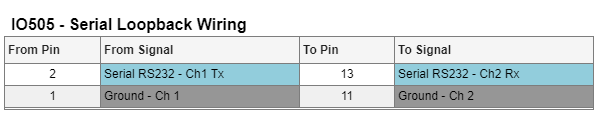

## Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_Serial_ReadHeaderLoopback';
open_system(modelName);

### Model Description

Please note that by default this Simulink model is configured to be used with an IO503. To change to another serial I/O module, simply change the **Module Type** in all the serial blocks.

In the model, two sine wave signals and one pulse signal are encoded to an ASCII data stream and transmitted by channel 1 using the **Legacy Mode.** The legacy mode is used as it supports the same data type as the [ASCII Encode](https://mathworks.com/help/slrealtime/io_ref/asciiencode.html) block outputs, which is a NULL-terminated character string with a delimiter after the ASCII-encoded variable. Consequently, it is easy to extract the encoded variable and only complete messages are decoded. The transmit software FIFO size must be configured in the [Serial - Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_setup) block to ensure it is sufficiently large enough to store at least two complete messages in case one message is not entirely sent out before the next message is written to the buffer.

On the receiving side, the ASCII data stream from channel 2 is buffered and then decoded to extract the original signals. Buffering is required as a partially complete message might be available when the [Serial - Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_read) block is executed. To ensure compatibility with the [ASCII Decode](https://mathworks.com/help/slrealtime/io_ref/asciidecode.html) blocks' input port data type, the receive track is configured to use the NULL-terminated character string which is sent from channel 1. The size of the buffer is set to double the size of the receive software FIFO configured in the [Serial - Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_setup) block to prevent data loss if there is an overflow. The receive software FIFO is configured to the same size as the transmit software FIFO to ensure it can hold the transmitted message. The [FIFO Read HDRS](https://mathworks.com/help/slrealtime/io_ref/fiforeadhdrs.html) block parses the data stream received for the specified headers ('`sine1`', '`pulse`', '`sine2`') and the termination ('`\r\n`' = [13 10]) in order to extract a complete message containing the three sub messages. The maximum read size is set to the same size as the software FIFO to ensure that all messages are read if multiple messages are available. Once a complete message is available in the software FIFO, the message is split up into the three different sub messages and then decoded by the [ASCII Decode](https://mathworks.com/help/slrealtime/io_ref/asciidecode.html) blocks in order to obtain double values for further processing.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### **Possible Issues**

A problem has been encountered with the FIFO Write block used in the legacy configuration with the ASCII workflow. The error PopUp "FIFO overflow: FIFO overflow" may appear. 

The referenced FIFO is not linked to the Serial FIFO of the target or the module. In the ASCII workflow, the data is written to a dedicated FIFO and immediately read back so it can be formatted correctly for ASCII decoding. The FIFO Write writes to the FIFO, and the FIFO Read reads the FIFO when it detects the delimiter. 

If, for some reason, the messages are not sent correctly, the delimiter may not be transmitted In this case, the FIFO is filled but not emptied, eventually overflowing. One of the causes of the incorrect transmission is unreliable wiring of the terminal board. This ASCII workflow is not tolerant of wiring issues.

To resolve this issue there are three solutions:

- Check the wiring.

- Uncheck the "Read to delimiter" option in the FIFO Read block. (This option is usually suggested to have checked in the ASCII workflow.)

- Do not use the ASCII workflow with the FIFO blocks.

### Check the Results

To check if the loopback is working as expected and the variables are correctly extracted from the ASCII data stream, open the Simulink scope connected to the [ASCII Decode](https://mathworks.com/help/slrealtime/io_ref/asciidecode.html) blocks. Two sine waves and a pulse signal must be displayed:

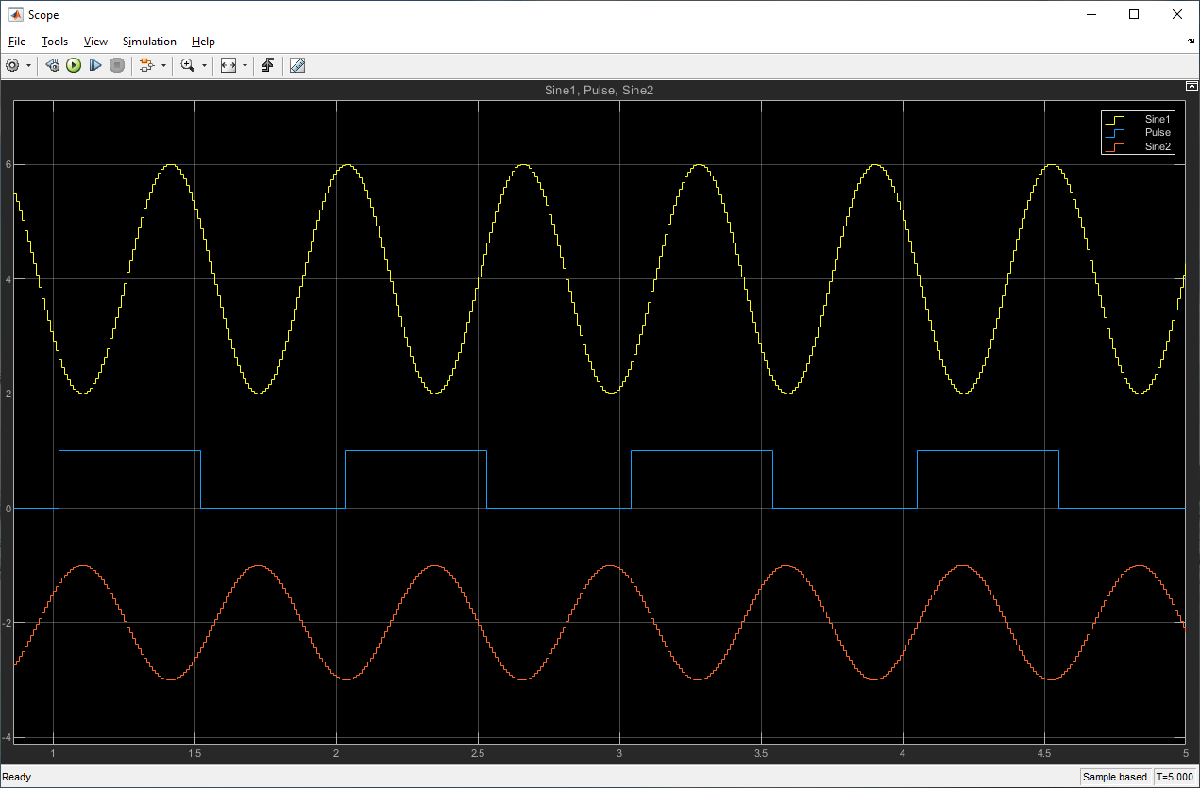

## Additional References

- [Serial documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io50Xio581)